## Grid Convergence Method

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

[Establishing Grid Convergence – curiosityFluids](https://curiosityfluids.com/2016/09/09/establishing-grid-convergence/)

% Given Data: Grid Refinement Levels and Corresponding Results

#### Input manually

h = [1/10, 1/20, 1/40];      % Grid Spacings (inverse of number of elements)
phi = [0.234, 0.198, 0.184]; % Simulation results (e.g. load factor in Fusion 360)

% Refinement Ratios
r21 = h(1) / h(2);  % Coarse to medium
r32 = h(2) / h(3);  % Medium to fine

% Calculate Apparent Order of Accuracy (p)
p = log((phi(3) - phi(2)) / (phi(2) - phi(1))) / log(r32);

% Richardson Extrapolated Value
phi_ext = phi(3) + (phi(3) - phi(2)) / (r32^p - 1);

% Grid Convergence Index (GCI) Calculation
GCI21 = (1.25 * abs((phi(2) - phi(1))) / (phi(1) * (r21^p - 1))) * 100;
GCI32 = (1.25 * abs((phi(3) - phi(2))) / (phi(2) * (r32^p - 1))) * 100;

% Display Results
fprintf('Grid Convergence Study Results:\n');

Grid Convergence Study Results:


fprintf('Refinement Ratio (r21): %.2f, (r32): %.2f\n', r21, r32);

Refinement Ratio (r21): 2.00, (r32): 2.00


fprintf('Estimated Order of Accuracy (p): %.3f\n', p);

Estimated Order of Accuracy (p): -1.363


fprintf('Richardson Extrapolated Value: %.5f\n', phi_ext);

Richardson Extrapolated Value: 0.20691


fprintf('GCI (Coarse to Medium) = %.3f%%\n', GCI21);

GCI (Coarse to Medium) = -31.469%


fprintf('GCI (Medium to Fine) = %.3f%%\n', GCI32);

GCI (Medium to Fine) = -14.463%


- **If GCI values remain high (>5%)** → The mesh is not yet independent, requiring finer mesh levels.

- **If GCI21 > GCI32 → The solution is still converging, and additional refinement is recommended.**

- **If results oscillate or order of accuracy (p) is lower than expected** → Numerical errors may exist, requiring adjustments in **solver settings, boundary conditions, or meshing strategy**.

% Decision Criteria for Mesh Selection
threshold_GCI = 5;         % Acceptable GCI percentage for mesh independence
GCI_diff_threshold = 1.5;  % Threshold for difference between GCI values

if GCI32 < threshold_GCI && abs(GCI21 - GCI32) < GCI_diff_threshold
    fprintf('✅ Selected Mesh Level: %d Elements (1/h = %.2f)\n', ...
        round(1/h(3)), 1/h(3));
    fprintf('Mesh is independent. Further refinement is unnecessary.\n');
elseif GCI21 > GCI32
    fprintf('⚠️ Warning: Mesh is still refining. GCI21 > GCI32 indicates ongoing convergence.\n');
    fprintf('Further refinement is recommended.\n');
else
    fprintf('❌ Warning: Mesh is not yet independent. GCI values are still high.\n');
    fprintf('Further mesh refinement is required.\n');
end

❌ Warning: Mesh is not yet independent. GCI values are still high.


Further mesh refinement is required.


**Increase mesh density by adding a finer level and repeating the GCI calculation.**

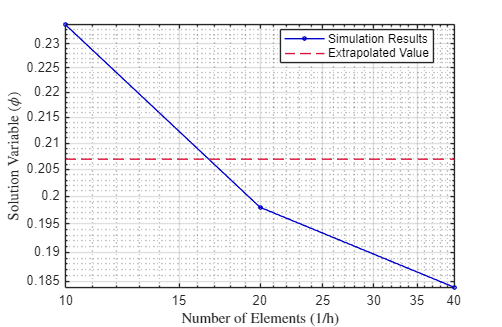


% Plot Convergence Trend
figure;

loglog(1./h, phi, 'o-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1, 'Markersize', 2.5);
hold on;

loglog(1./h, phi_ext * ones(size(h)), '--', 'Color',  [220/255 20/255 60/255], 'LineWidth', 0.5);

xlabel('Number of Elements (1/h)', 'Interpreter', 'latex');
ylabel('Solution Variable ($\phi$)', 'Interpreter', 'latex');
legend('Simulation Results', 'Extrapolated Value', 'Location', 'Best');

grid on;
hold off

% Set figure size
set(gcf, 'Position', [0 0 500 325]);

% Plot mesh convergence study

#### **Input manually**

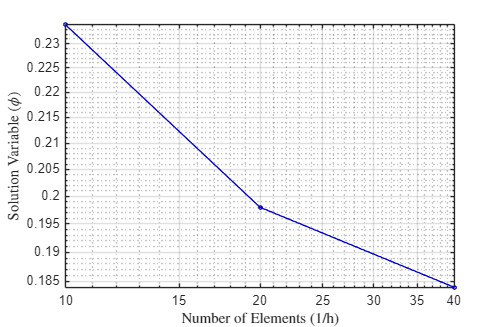

h_total = [1/10, 1/20, 1/40];      % Manually adjusted
phi_total = [0.234, 0.198, 0.184]; % Simulation results (e.g. load factor in Fusion 360)

figure;

loglog(1./h_total, phi_total, 'o-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1, 'Markersize', 2.5);

xlabel('Number of Elements (1/h)', 'Interpreter', 'latex');
ylabel('Solution Variable ($\phi$)', 'Interpreter', 'latex');

grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 325]);